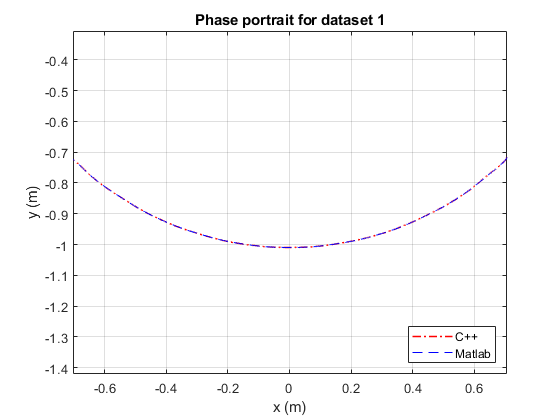

%set 1

clear
clc
format long

m1=1;
m2=1;
l1=0.01;
l2=1;
g=9.81;

y0=[0;0;0.785;0];

h=0.0001;
tf=1;

%mit
%f = @(t,y) [y(2); (-g*(2*m1+m2)*sin(y(1))-m2*g*sin(y(1)-2*y(3))-2*sin(y(1)-y(3))*m2*((y(4)^2)*l2+(y(2)^2)*l1*cos(y(1)-y(3))))/(l1*(2*m1+m2-m2*cos(2*y(1)-2*y(3)))); y(4); (2*sin(y(1)-y(3))*((y(2)^2)*l1*(m1+m2)+g*(m1+m2)*cos(y(1))+(y(4)^2)*l2*m2*cos(y(1)-y(3))))/(l2*(2*m1+m2-m2*cos(2*y(1)-2*y(3))))];

%handout
f = @(t,y) [y(2); (-m2*cos(y(1)-y(3))*l1*(y(2)^2)*sin(y(1)-y(3))+m2*cos(y(1)-y(3))*g*sin(y(3))-m2*l2*(y(4)^2)*sin(y(1)-y(3))-(m1+m2)*g*sin(y(1)))/(l1*(m1+m2-m2*(cos(y(1)-y(3)))^2)) ; y(4); (m1+m2)*(l1*(y(2)^2)*sin(y(1)-y(3))+((y(4)^2)*sin(y(1)-y(3))*cos(y(1)-y(3))*m2*l2)/(m1+m2)+cos(y(1)-y(3))*g*sin(y(1))-g*sin(y(3)))/(l2*(m1+m2*(sin(y(1)-y(3)))^2))];

tspan=[0, tf];

[t,y] = RungeKutta4(f,tspan,y0,h);

x1 = l1*sin(y(1,:));
y1=-l1*cos(y(1,:));
x2=x1+l2*sin(y(3,:));
y2=y1-l2*cos(y(3,:));

data=readmatrix('output1.txt');

x2c=data(:,4);
y2c=data(:,5);

a=figure;
plot(x2c,y2c,'-.r','Linewidth',1.15)
grid on
axis equal
hold on
plot(x2,y2,'--b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait for dataset 1')
legend('C++','Matlab','Location','southeast')
hold off
saveas(a,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q6\Q6a','Q6a1.png'))

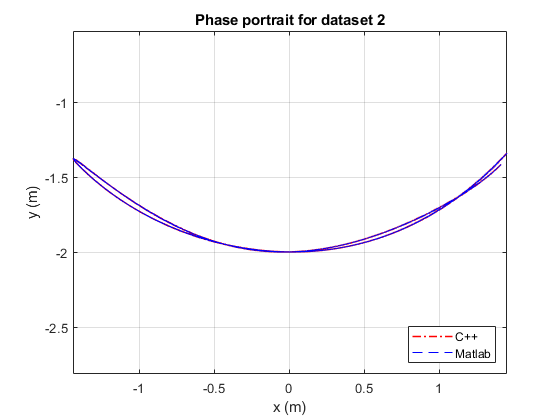




%set 2

clear
clc
format long

m1=1;
m2=1;
l1=1;
l2=1;
g=9.81;

y0=[0.785;0;0.785;0];

h=0.001;
tf=10;

%mit
%f = @(t,y) [y(2); (-g*(2*m1+m2)*sin(y(1))-m2*g*sin(y(1)-2*y(3))-2*sin(y(1)-y(3))*m2*((y(4)^2)*l2+(y(2)^2)*l1*cos(y(1)-y(3))))/(l1*(2*m1+m2-m2*cos(2*y(1)-2*y(3)))); y(4); (2*sin(y(1)-y(3))*((y(2)^2)*l1*(m1+m2)+g*(m1+m2)*cos(y(1))+(y(4)^2)*l2*m2*cos(y(1)-y(3))))/(l2*(2*m1+m2-m2*cos(2*y(1)-2*y(3))))];

%handout
f = @(t,y) [y(2); (-m2*cos(y(1)-y(3))*l1*(y(2)^2)*sin(y(1)-y(3))+m2*cos(y(1)-y(3))*g*sin(y(3))-m2*l2*(y(4)^2)*sin(y(1)-y(3))-(m1+m2)*g*sin(y(1)))/(l1*(m1+m2-m2*(cos(y(1)-y(3)))^2)) ; y(4); (m1+m2)*(l1*(y(2)^2)*sin(y(1)-y(3))+((y(4)^2)*sin(y(1)-y(3))*cos(y(1)-y(3))*m2*l2)/(m1+m2)+cos(y(1)-y(3))*g*sin(y(1))-g*sin(y(3)))/(l2*(m1+m2*(sin(y(1)-y(3)))^2))];

tspan=[0, tf];

[t,y] = RungeKutta4(f,tspan,y0,h);

x1 = l1*sin(y(1,:));
y1=-l1*cos(y(1,:));
x2=x1+l2*sin(y(3,:));
y2=y1-l2*cos(y(3,:));

data=readmatrix('output2.txt');

x2c=data(:,4);
y2c=data(:,5);

b=figure;
plot(x2c,y2c,'-.r','Linewidth',1.15)
grid on
axis equal
hold on
plot(x2,y2,'--b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait for dataset 2')
legend('C++','Matlab','Location','southeast')
hold off
saveas(b,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q6\Q6a','Q6a2.png'))

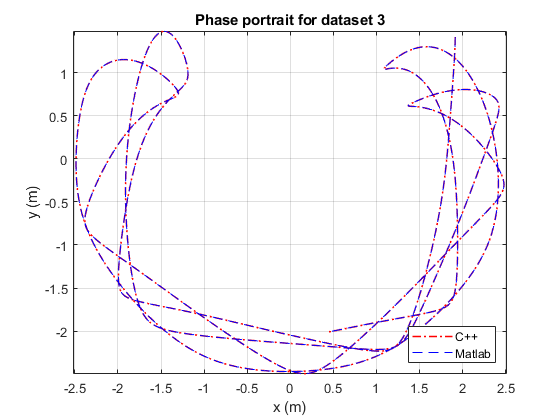

maxdiff =      4.999510549552610e-06





%set 3

clear
clc
format long

m1=1;
m2=2;
l1=0.5;
l2=2;
g=9.81;

y0=[1.571;0;2.356;0];

h=0.001;
tf=10;

%mit
%f = @(t,y) [y(2); (-g*(2*m1+m2)*sin(y(1))-m2*g*sin(y(1)-2*y(3))-2*sin(y(1)-y(3))*m2*((y(4)^2)*l2+(y(2)^2)*l1*cos(y(1)-y(3))))/(l1*(2*m1+m2-m2*cos(2*y(1)-2*y(3)))); y(4); (2*sin(y(1)-y(3))*((y(2)^2)*l1*(m1+m2)+g*(m1+m2)*cos(y(1))+(y(4)^2)*l2*m2*cos(y(1)-y(3))))/(l2*(2*m1+m2-m2*cos(2*y(1)-2*y(3))))];

%handout
f = @(t,y) [y(2); (-m2*cos(y(1)-y(3))*l1*(y(2)^2)*sin(y(1)-y(3))+m2*cos(y(1)-y(3))*g*sin(y(3))-m2*l2*(y(4)^2)*sin(y(1)-y(3))-(m1+m2)*g*sin(y(1)))/(l1*(m1+m2-m2*(cos(y(1)-y(3)))^2)) ; y(4); (m1+m2)*(l1*(y(2)^2)*sin(y(1)-y(3))+((y(4)^2)*sin(y(1)-y(3))*cos(y(1)-y(3))*m2*l2)/(m1+m2)+cos(y(1)-y(3))*g*sin(y(1))-g*sin(y(3)))/(l2*(m1+m2*(sin(y(1)-y(3)))^2))];

tspan=[0, tf];

[t,y] = RungeKutta4(f,tspan,y0,h);

x1 = l1*sin(y(1,:));
y1=-l1*cos(y(1,:));
x2=x1+l2*sin(y(3,:));
y2=y1-l2*cos(y(3,:));

data=readmatrix('output3.txt');

x2c=data(:,4);
y2c=data(:,5);

c=figure;
plot(x2c,y2c,'-.r','Linewidth',1.15)
grid on
axis equal
hold on
plot(x2,y2,'--b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait for dataset 3')
legend('C++','Matlab','Location','southeast')
hold off
saveas(c,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q6\Q6a','Q6a3.png'))

function [t,y,k1,k2,k3,k4] = RungeKutta4(f,tspan,y0,h)
% Fourth-order Runge-Kutta

m = length(y0);
t = tspan(1):h:tspan(2);
y = zeros(m,length(t));
y(:,1) = y0;

for i = 1:length(t)-1
    k1 = h*f(t(i),y(:,i));
    k2 = h*f(t(i)+h/2,y(:,i)+k1/2);
    k3 = h*f(t(i)+h/2,y(:,i)+k2/2);
    k4 = h*f(t(i)+h,y(:,i)+k3);
    y(:,i+1) = y(:,i) + k1/6 + (k2+k3)/3 + k4/6;

end
end